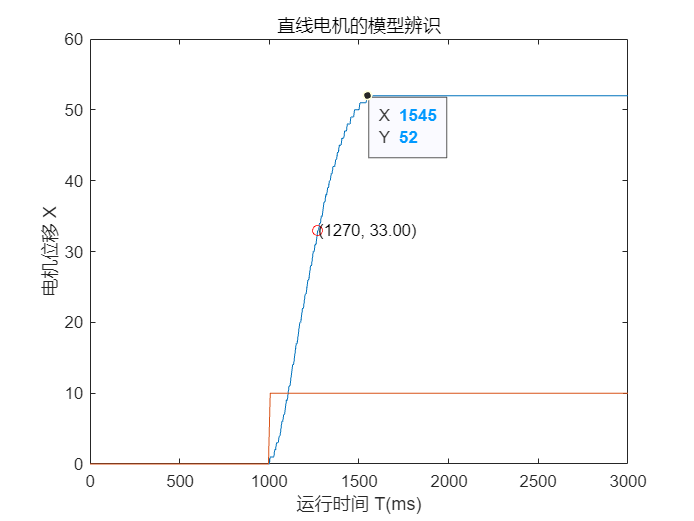

clc
close all
clear

data=xlsread("data_Motor.xlsx");
y=data(:,1); %读取直线电机位置数据
t0=data(:,2); %读取电机运动时间(未使用)
T = 0:5:3000;%定义时间序列

%定义延时为1s，峰值为10V的阶跃信号(实际为1V)
u = 10*heaviside(T-1000);
plot(T,y) ; %绘制实际响应曲线
hold on;
title('直线电机的模型辨识');
xlabel('运行时间 T(ms)');
ylabel('电机位移 X');
plot(T,u) ; %绘制阶跃信号曲线

% 找到曲线最大值
[max_value, max_index] = max(y);
%%在图中显示响应终值和上升时间%%
response_end = max(y); %获取响应终值y_max
peak_time = (max_index-1)*5; %获取上升时间ts
ax2 = gca;
chart2 = ax2.Children(2);
datatip(chart2,response_end,peak_time);

% 计算最大值0.632倍的位置坐标
threshold = 0.632 * max_value;
p = find(y >= threshold, 1);

% 在图中展示最大值0.632倍的位置
plot(T(p), y(p), 'ro');
text(T(p), y(p), sprintf('(%d, %.2f)', T(p), y(p)));
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%设置用于模型验证的增益及时间常数%%
K = 63;
t = 0.360;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%绘制所求传递函数的阶跃响应
num=K;
den=[t 1];
sys = tf(num,den);
h=step(sys,0:0.1:5);
plot(h)
title('直线电机模型参数验证');
xlabel('时间T（s）10×');
ylabel('电机位移X');
grid on
xlim([-10 40])
ylim([-0 70])